%Investigation of 3 state model
v=load('membrane_potential_sample_ref.txt');

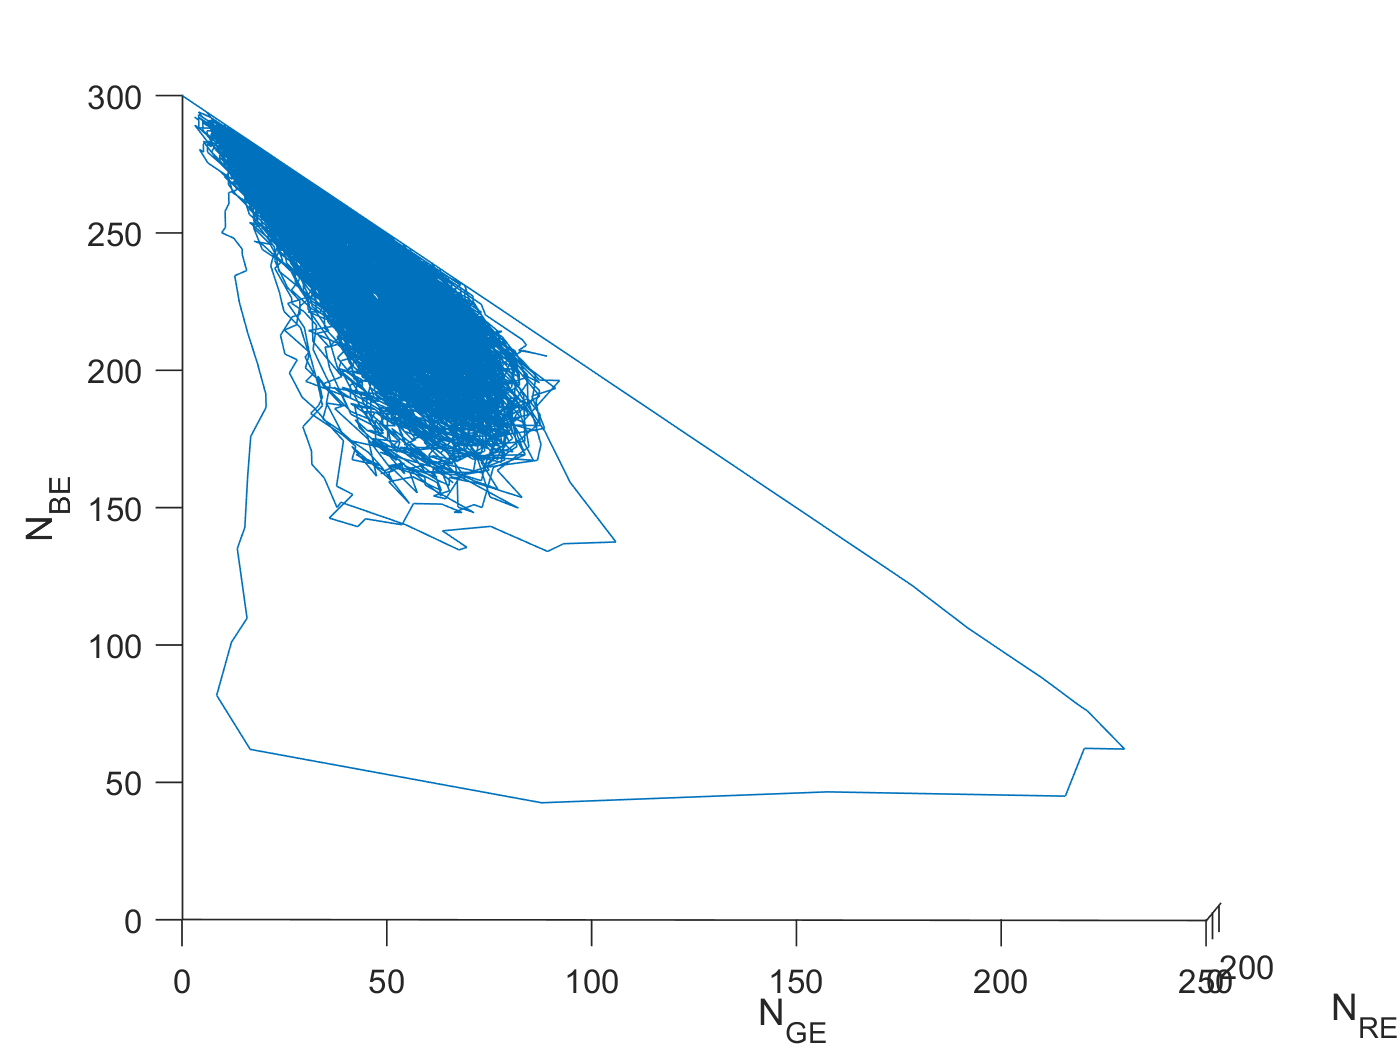

gate = 74;
mr = -66;
ve = v(:,1:300);
vi = v(:,301:400);
[r,c] = size(ve);
e3 = zeros(r,3); % representing N_RE, N_GE, N_BE
e3(:,1) = sum((ve<mr),2);
e3(:,2) = sum((ve>gate),2);
e3(:,3) = c-e3(:,1)-e3(:,2);

plot3(e3(:,1),e3(:,2),e3(:,3));
xlabel('N_{RE}')
ylabel('N_{GE}')
zlabel('N_{BE}')

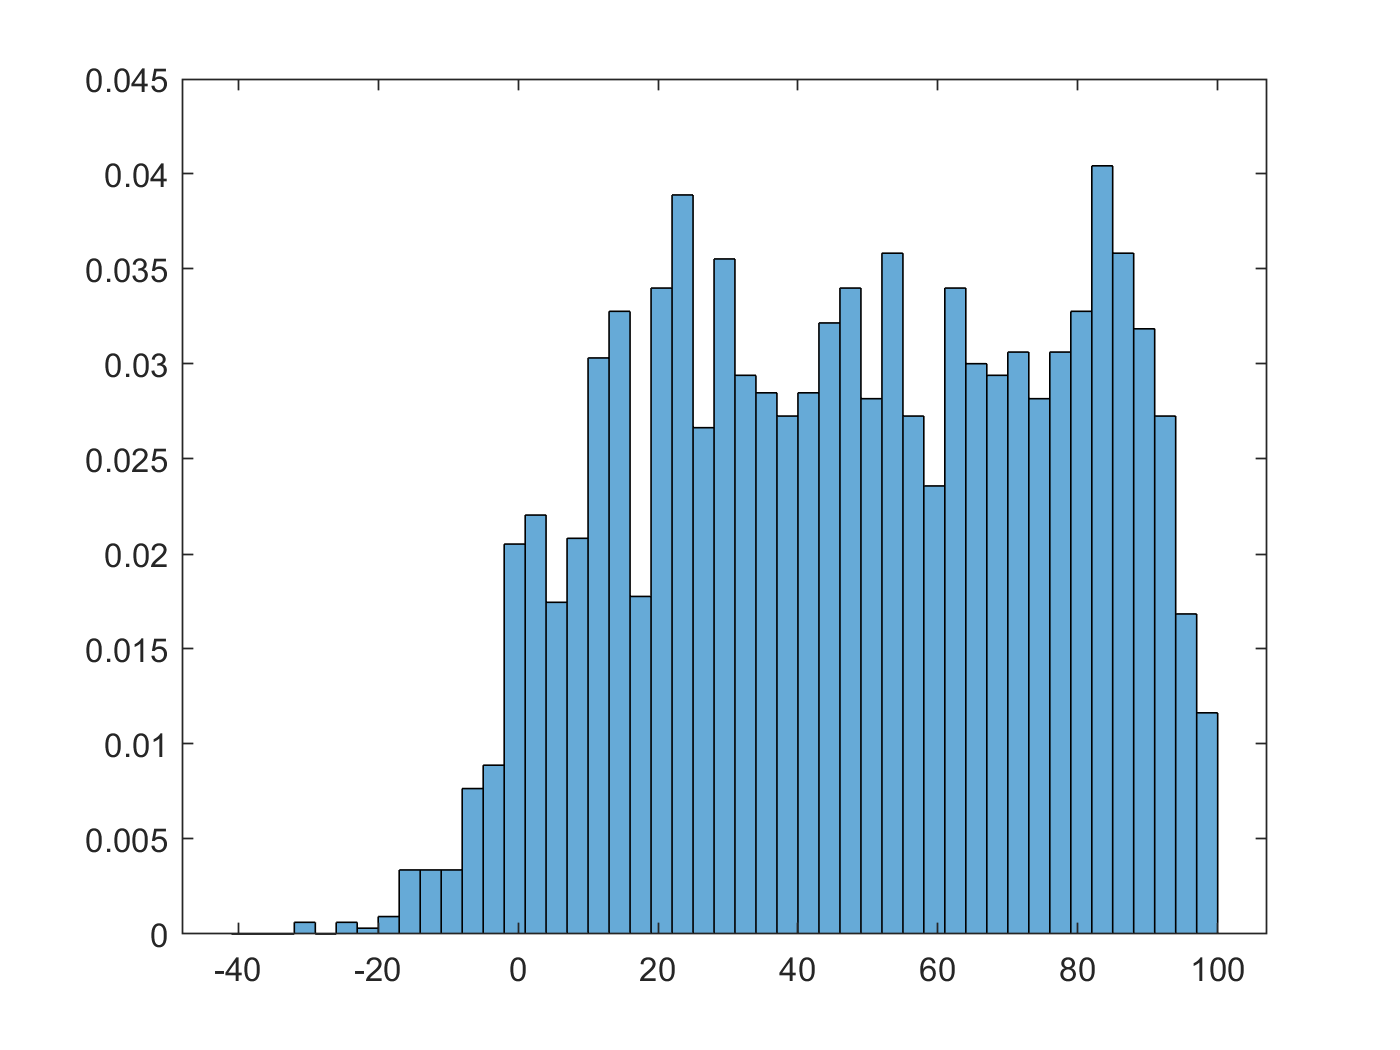

result=e3(:,2)./e3(:,3);
index = (e3(:,1)>0).*(e3(:,1)<5).*(result<0.35).*(result>0.3);
index = logical(index);
ve_selected = ve(index,:);
histogram(ve_selected(ve_selected>=mr),[-41:3:100],'Normalization',"probability")

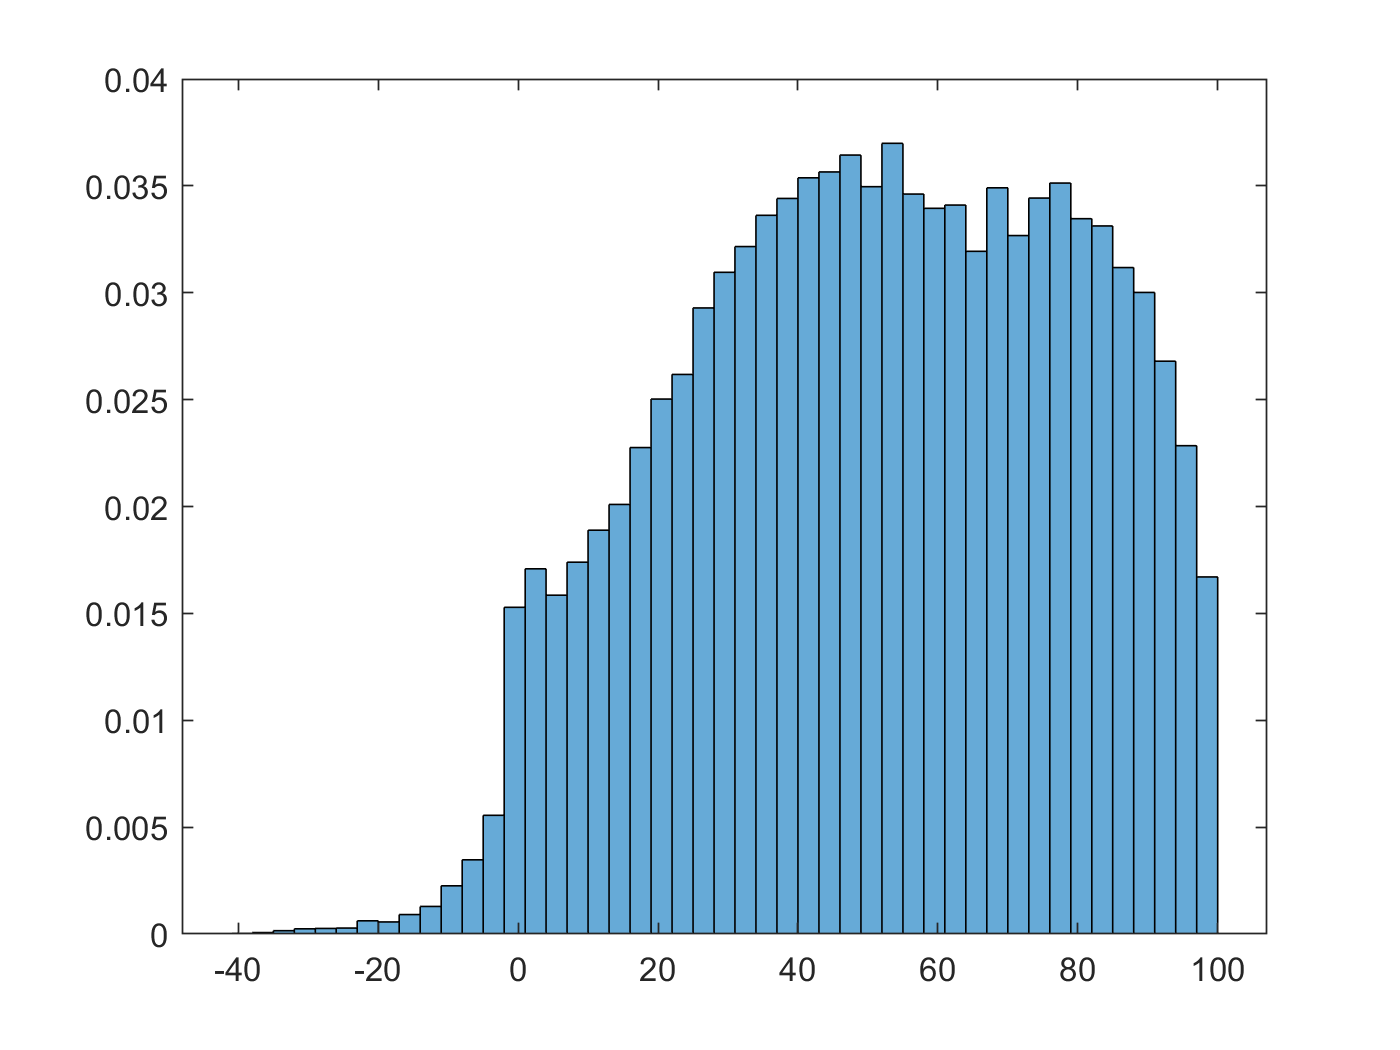

result=e3(:,2)./e3(:,3);
index = (e3(:,1)>=15).*(e3(:,1)<=20).*(result<0.35).*(result>0.3);
index = logical(index);
ve_selected = ve(index,:);
histogram(ve_selected(ve_selected>=mr),[-41:3:100],'Normalization',"probability")

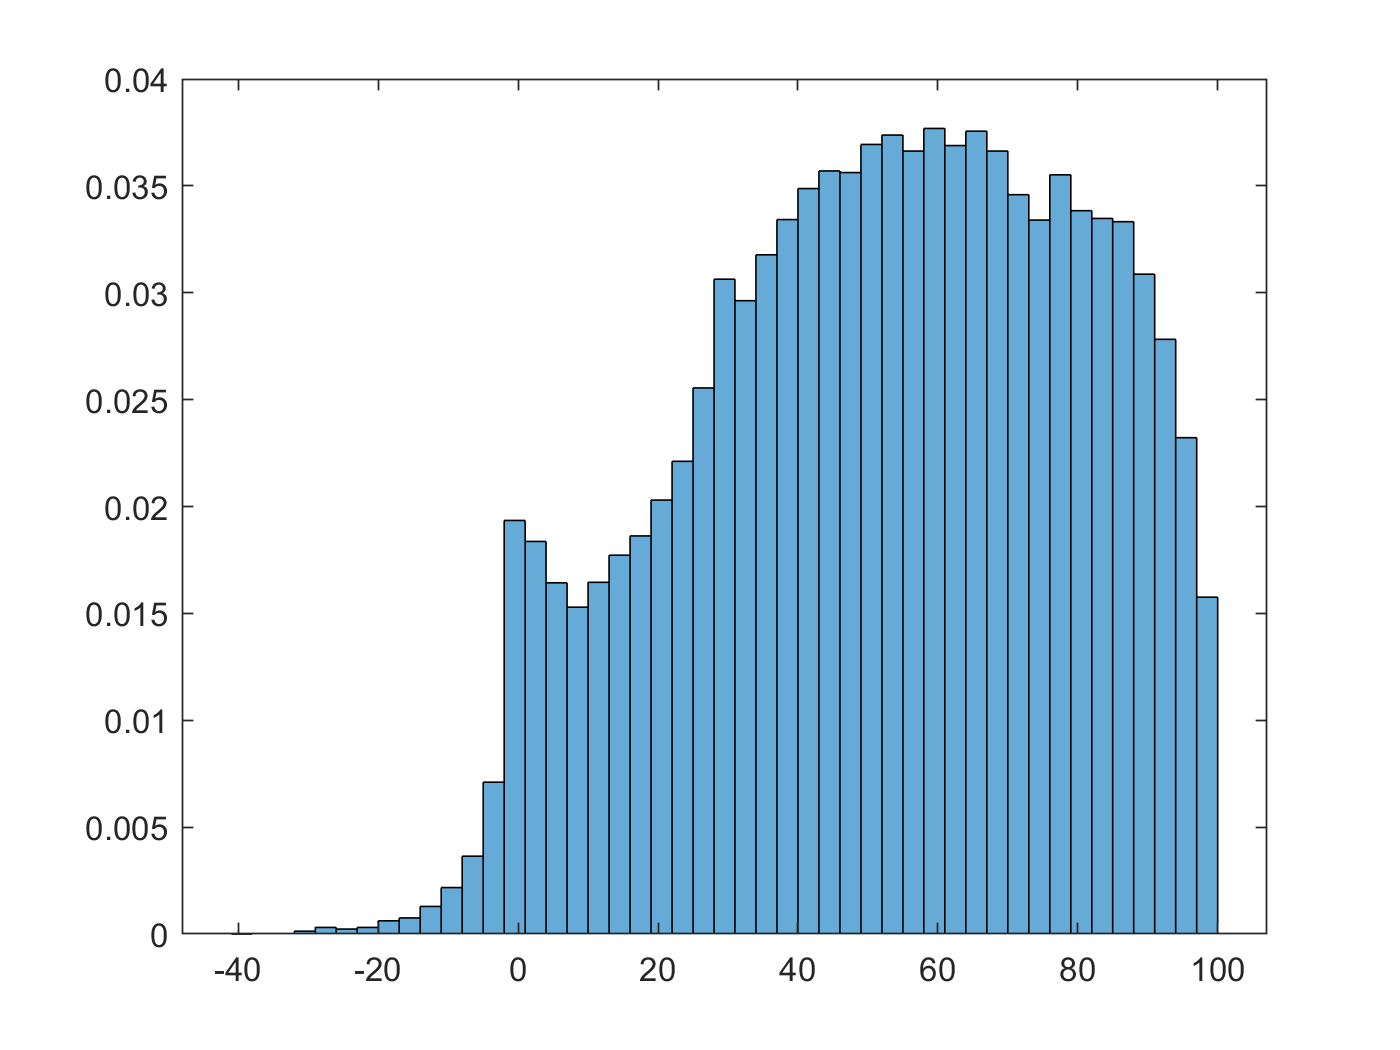

result=e3(:,2)./e3(:,3);
index = (e3(:,1)>=25).*(e3(:,1)<=30).*(result<0.35).*(result>0.3);
index = logical(index);
ve_selected = ve(index,:);
histogram(ve_selected(ve_selected>=mr),[-41:3:100],'Normalization',"probability")

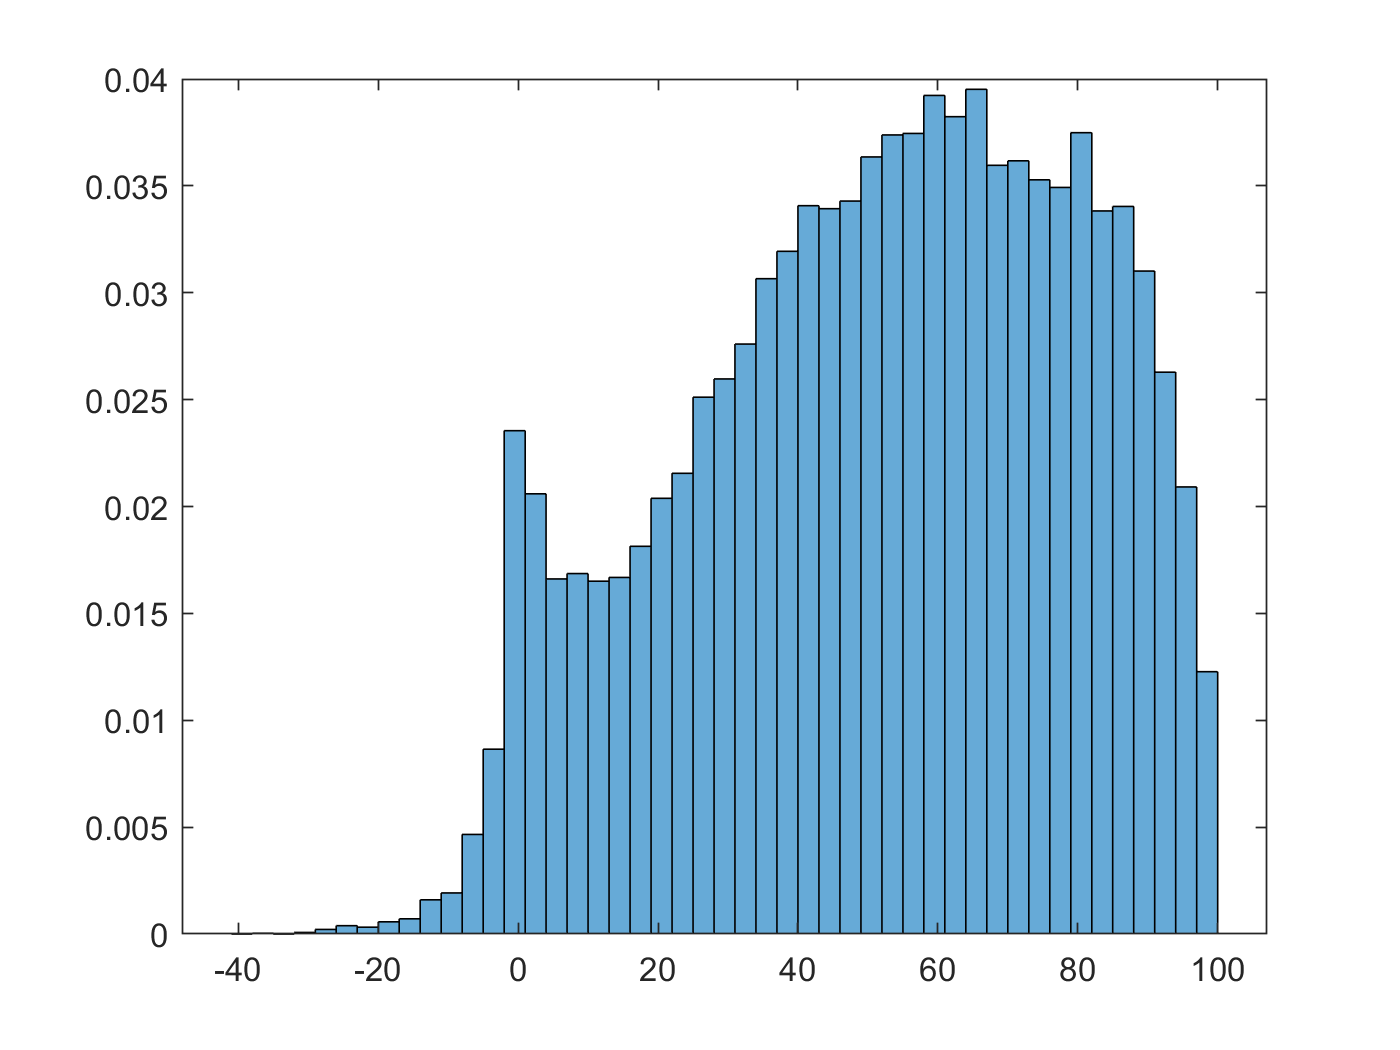

result=e3(:,2)./e3(:,3);
index = (e3(:,1)>=35).*(e3(:,1)<=40).*(result<0.35).*(result>0.3);
index = logical(index);
ve_selected = ve(index,:);
histogram(ve_selected(ve_selected>=mr),[-41:3:100],'Normalization',"probability")

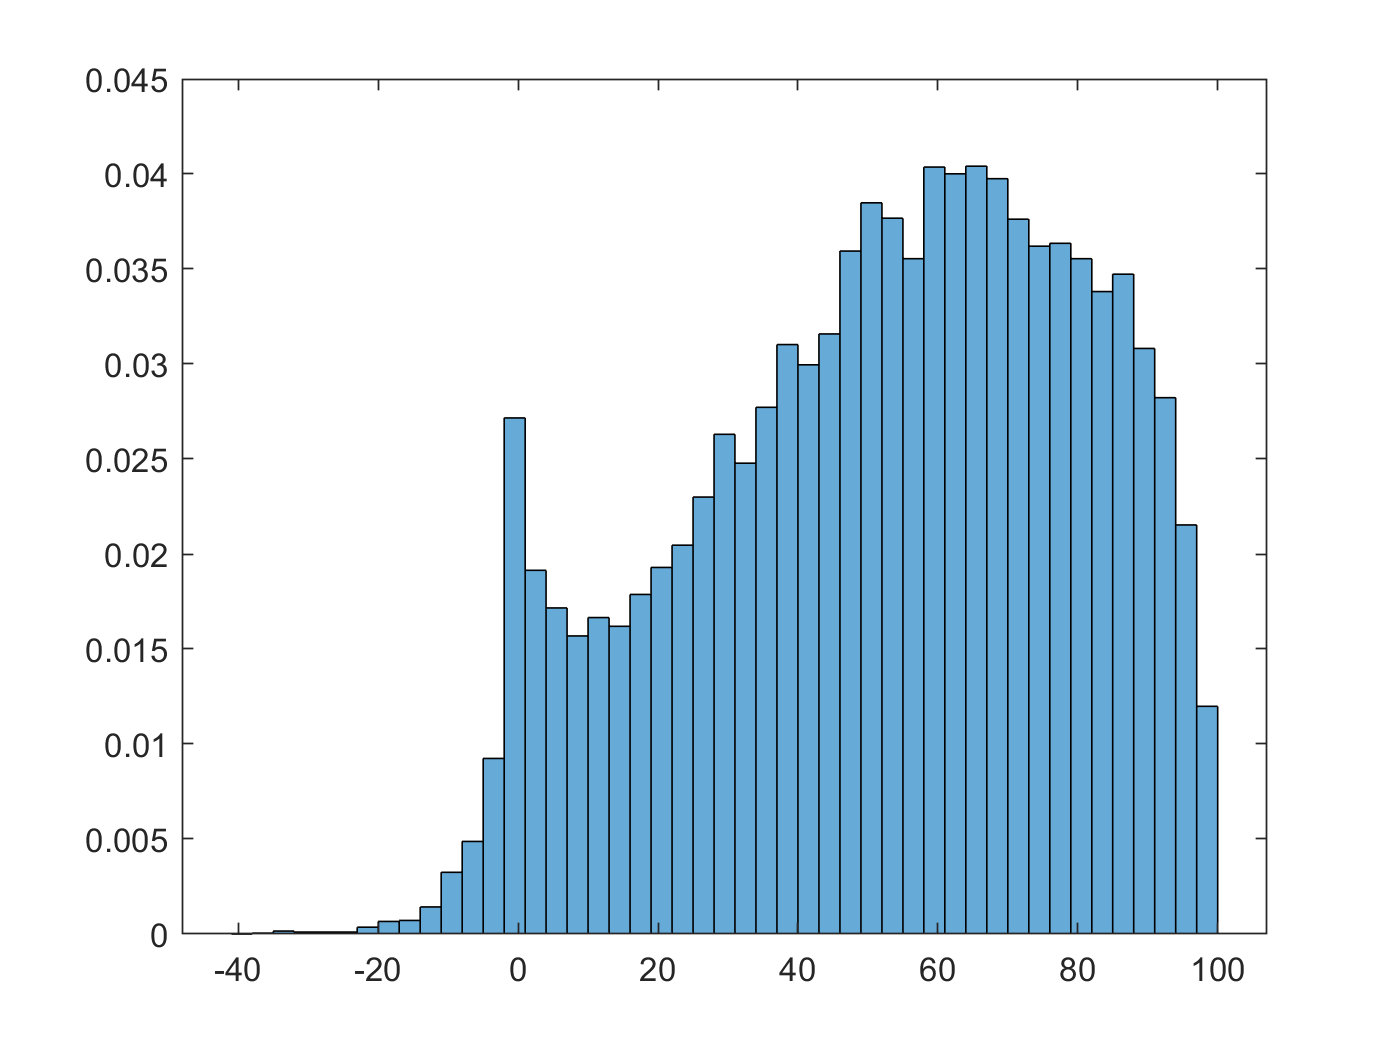

result=e3(:,2)./e3(:,3);
index = (e3(:,1)>=45).*(e3(:,1)<=50).*(result<0.35).*(result>0.3);
index = logical(index);
ve_selected = ve(index,:);
histogram(ve_selected(ve_selected>=mr),[-41:3:100],'Normalization',"probability")

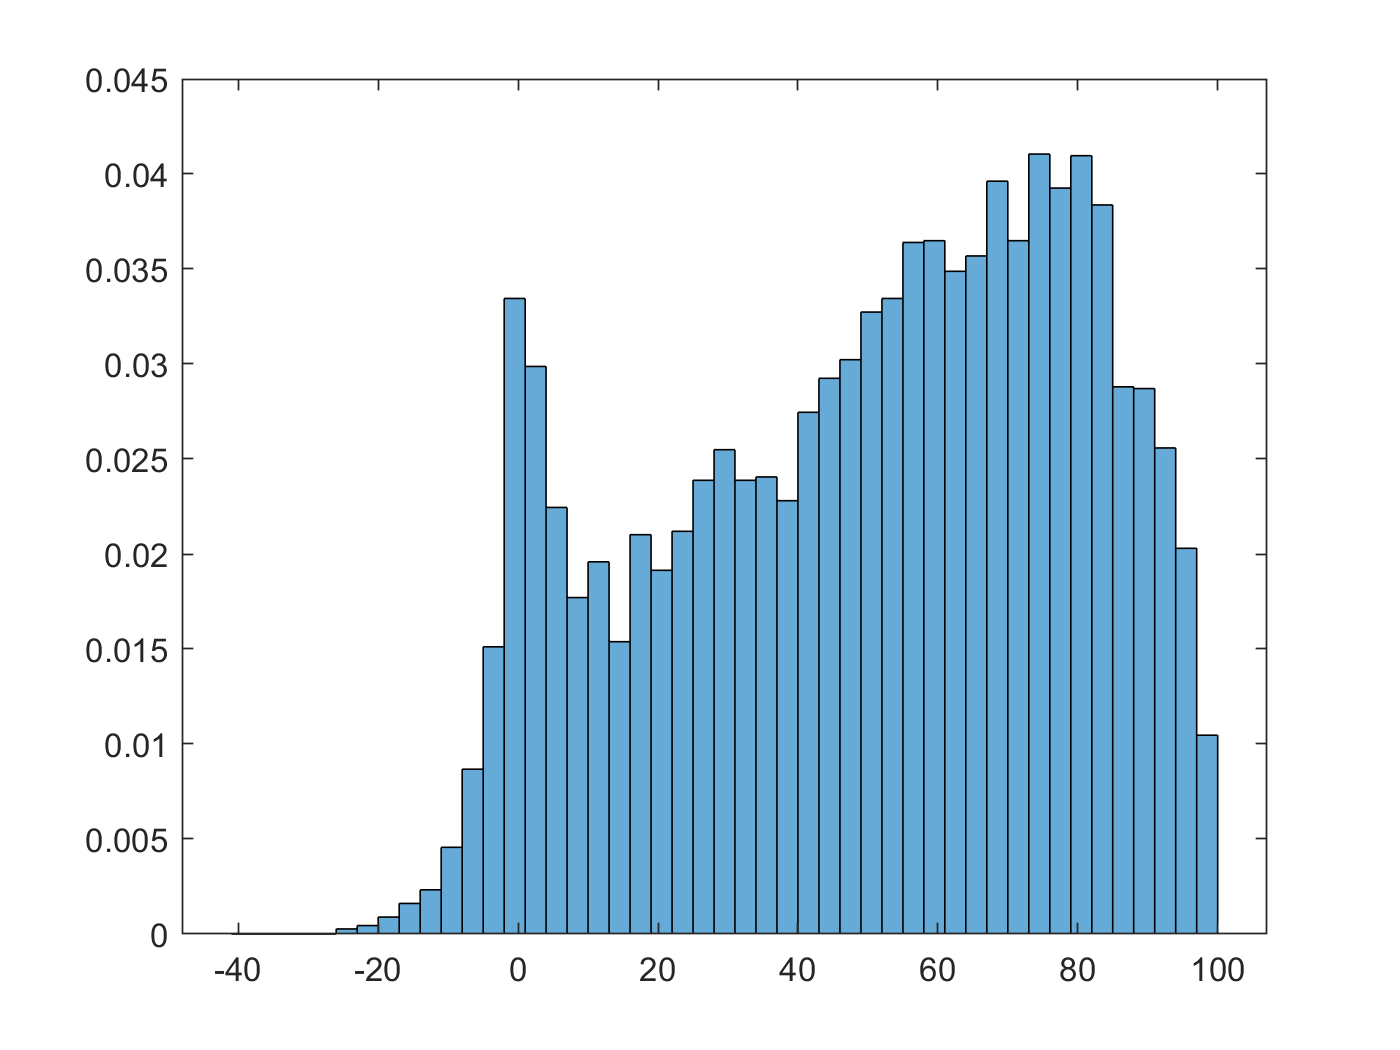

result=e3(:,2)./e3(:,3);

index = (e3(:,1)>=55).*(e3(:,1)<=60).*(result<0.35).*(result>0.3);
index = logical(index);
ve_selected = ve(index,:);
histogram(ve_selected(ve_selected>=mr),[-41:3:100],'Normalization',"probability")

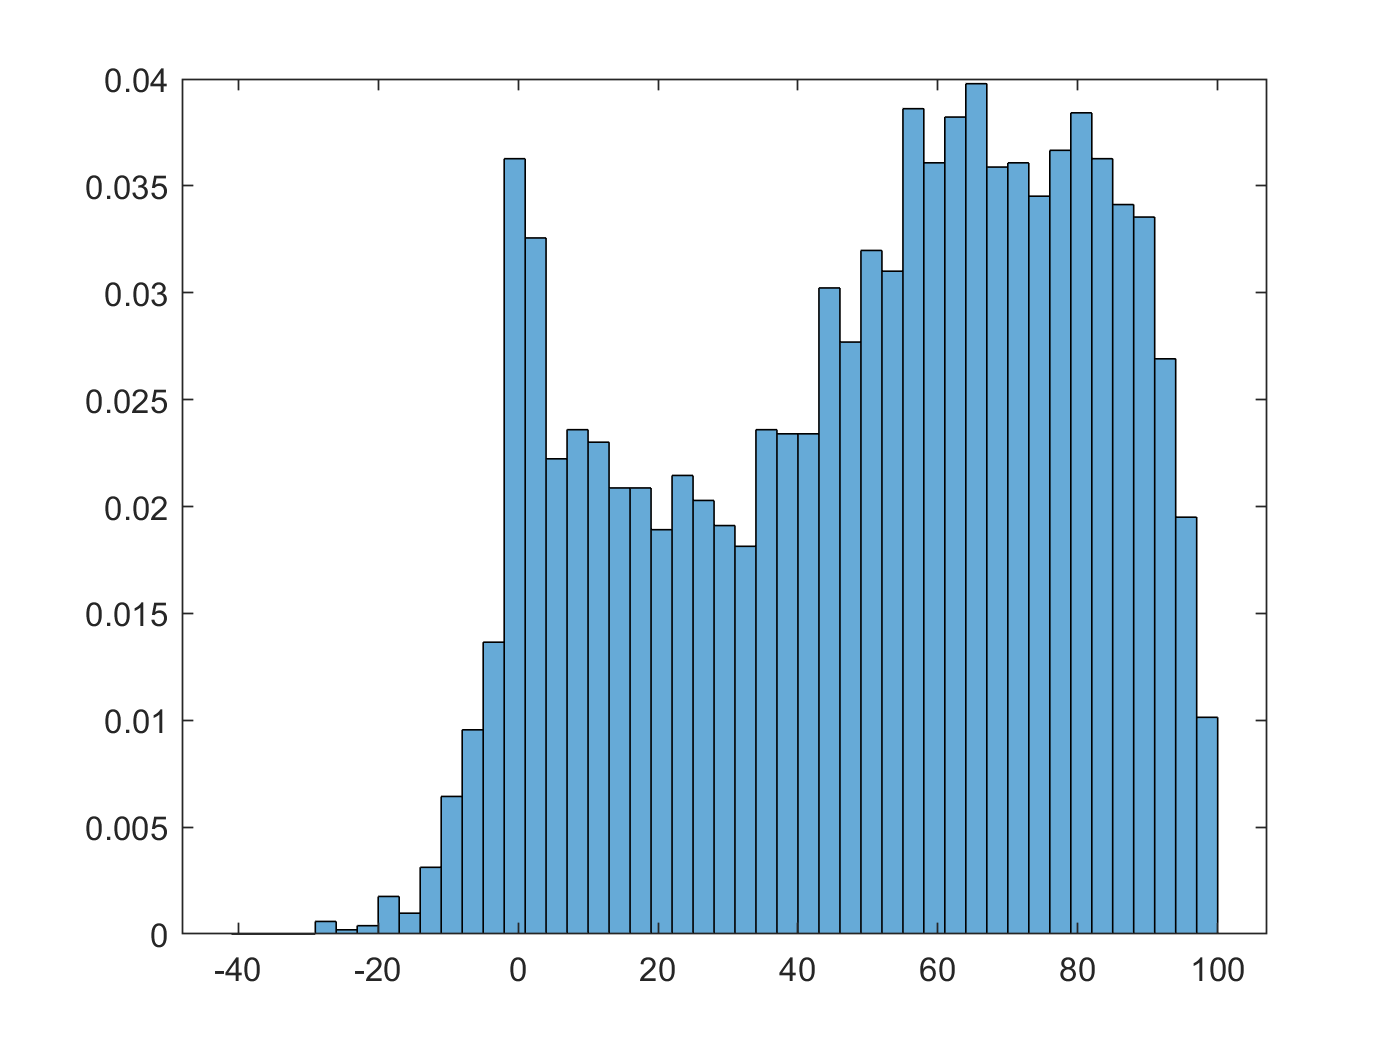

result=e3(:,2)./e3(:,3);
index = (e3(:,1)>=65).*(e3(:,1)<=70).*(result<0.35).*(result>0.3);
index = logical(index);
ve_selected = ve(index,:);  
histogram(ve_selected(ve_selected>=mr),[-41:3:100],'Normalization',"probability")